% Define the data for lower limit, upper limit, and frequency
lowerLimits = [40,50,60,70,80,90,100,110,120]; 
upperLimits = [50,60,70,80,90,100,110,120,130]; 
frequencies = [36,87,121,154,133,95,50,30,10];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

        40            50            36   
        50            60            87   
        60            70           121   
        70            80           154   
        80            90           133   
        90           100            95   
       100           110            50   
       110           120            30   
       120           130            10   




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 78.35


fprintf('Median: %.2f\n', medianValue);

Median: 75.00


fprintf('Mode: %.2f\n', modeValue);

Mode: 75.00


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 18.34


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 68.30


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: 6.70


fprintf('Karl: %.2f\n', Karl);

Karl: 0.18


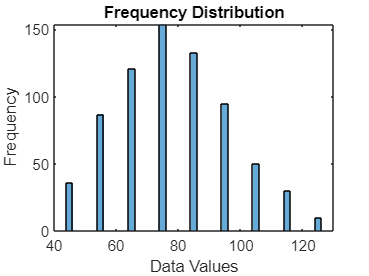


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');